#### Gambler brings $100 as initial budget. Leaves if he busts ($0) or if he makes double the intial budget ($200)

tic;
withdraw = 50;
numTurns = 1;
B = zeros(withdraw+1, withdraw+1);
p_win_b1 = 4/38;
p_win_b2 = 27/38;
M = 3;

for FROMbudget = 0:1:withdraw
    for TObudget = 0:1:withdraw
        if FROMbudget == 0
            if TObudget == 0
                B(FROMbudget+1, TObudget+1) = 1;
            end
        elseif FROMbudget == withdraw
            if TObudget == withdraw
                B(FROMbudget+1, TObudget+1) = 1;
            end
        elseif TObudget == FROMbudget - 1
            if mod(FROMbudget, M) == 0
                B(FROMbudget+1, TObudget+1) = 1-p_win_b1;
            else
                B(FROMbudget+1, TObudget+1) = 1-p_win_b2;
            end
        elseif TObudget == FROMbudget + 1
                if mod(FROMbudget, M) == 0
                    B(FROMbudget+1, TObudget+1) = p_win_b1;
                else
                    B(FROMbudget+1, TObudget+1) = p_win_b2;
                end
        end
    end
end

B_inf = B.^numTurns

B_inf =     1.0000         0         0         0         0         0
    0.2895         0    0.7105         0         0         0
         0    0.2895         0    0.7105         0         0
         0         0    0.8947         0    0.1053         0
         0         0         0    0.2895         0    0.7105
         0         0         0         0         0    1.0000


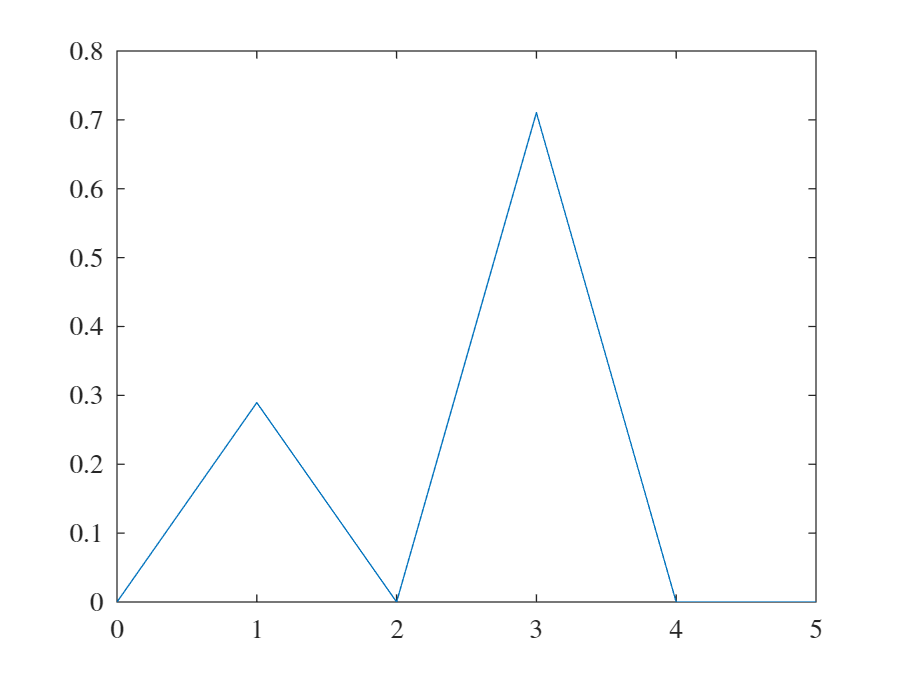

plot(0:1:withdraw, B_inf(3, :))

toc;

Elapsed time is 0.045410 seconds.
